%get eyex data into the form of display_target to start_target only; cells
%to contain the varying sizes. 
dataR2={};
for i= 1:size(dataR,1)
    dataR2{i}=dataR(i,12000:12000+(stamps(i,3)*1000));
end

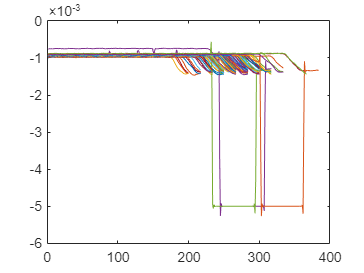

% plot data to verify that it looks okay 
for i= 1:size(dataR2,2); plot(dataR2{i}); hold on; end

smoothlength=10; %% this is the correct way to do velocity 6/16
dataR3=zeros(137,501);
for i= 1:size(dataB,1)
    dataR3(i,:)=data(i,12000:12500);
end

dataR3(29,:)=nan;

smooth_raw=zeros(137,501);
for i = 1:137
    smooth_raw(i,:)=smoothwin(dataR3(i,:),smoothlength);
end

velos_SR=zeros(137,500);
for i =1:137
    velos_SR(i,:)=abs(diff(smooth_raw(i,:)));
end

PeakVSR=zeros(137,1);
for i= 1:137
    [PeakVSR(i,:) Pindx(i,:)]=max(velos_SR(i,1+smoothlength:end-smoothlength)); %add and subtract smooth length to get rid of smoothing artifacts
end

velos_SR2=zeros(137,500); % just in case to test
for i =1:137  %just in case to test
    velos_SR2(i,:)=diff(abs(smooth_raw(i,:)));
end

PeakVSRS=[PeakVSR(1:28,:) ;PeakVSR(30:end,:)];
velos_SRS=[velos_SR(1:28,:);velos_SR(30:end,:)];

PeakVSR2=zeros(101,1);
for i= 1:101
    [PeakVSR2(i,:) Pindx2(i,:)]=max(velos_SR2(i,1+smoothlength:end-smoothlength));
end


pks=zeros(101,1); % trial for magnitude 
locs=zeros(101,1);
w=zeros(101,1);
p=zeros(101,1);
Mag=zeros(101,1)

Mag =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i =1:100 % size after scrub
    [pks(i,:),locs(i,:),w(i,:),p(i,:)]=findpeaks(velos_SRS(i,1+smoothlength:end-smoothlength)','Annotate','extents','MinPeakHeight',.000015,'MinPeakDistance',15,'WidthReference','halfheight');
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 2-by-1.

scrub_smooth=[smooth_raw(1:28,:);smooth_raw(30:end,:)];
scrub_smooth=[scrub_smooth(1:31,:);scrub_smooth(33:end,:)];

for i= 1:101
    if locs(i,:)+round(2*w(i,:))+1.5*smoothlength > 501
        Mag(i,:)=smooth_raw(i,locs(i,:)+round(1.5*w(i,:)))-smooth_raw(i,locs(i,:)-round(2*w(i,:))-1.5*smoothlength);
    else
        Mag(i,:)=smooth_raw(i,locs(i,:)+round(2*w(i,:))+1.5*smoothlength)-smooth_raw(i,locs(i,:)-round(2*w(i,:))-1.5*smoothlength);
    end
end
Mags=Mag(:);

Mags=[Mags(1:28,:);Mags(30:end,:)];

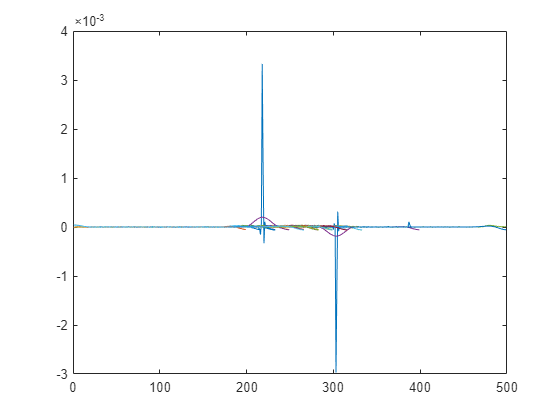

n=round(.5*size(dataR,1));

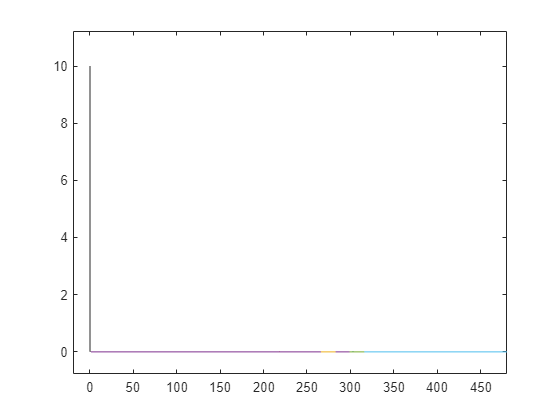

firsthalfsesh_mag = Mags(1:n,:);
secondhalfsesh_mag = Mags(n+1:end,:);

peakVeloscrubbed=rmoutliers(peakVelo);
m=round(.5*size(peakVeloscrubbed,1));
firsthalfsesh_peakvelo = peakVelo(1:m,:);
firsthalfsesh_peakvelo=rmoutliers(firsthalfsesh_peakvelo)
secondhalfsesh_peakvelo = peakVelo(m+1:end,:);

histogram(firsthalfsesh_mag,'EdgeColor','r','FaceColor','r', BinWidth=.00001)
hold on
histogram(secondhalfsesh_mag,'EdgeColor','b','FaceColor','b', BinWidth=.00001)
hold off 
legend('first half magnitude', 'second half magnitude')
title("saccade magnitude by session halves")

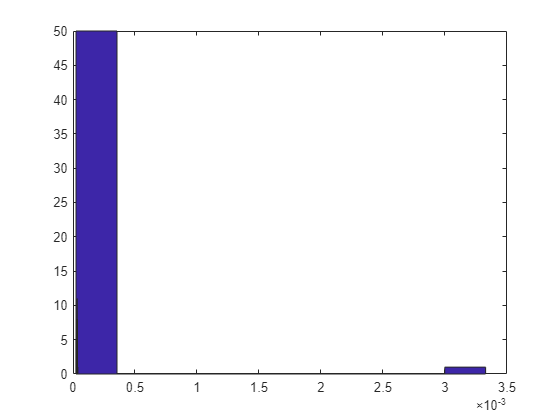

mean1st=mean(firsthalfsesh_mag)
mean2nd=mean(secondhalfsesh_mag)
std1st=std(firsthalfsesh_mag)
std2nd=std(secondhalfsesh_mag)

histogram(firsthalfsesh_peakvelo,'EdgeColor','r','FaceColor','r')
hold on

histogram(secondhalfsesh_peakvelo,'EdgeColor','b','FaceColor','b')
hold off 
legend('first half peak velocity', 'second half peak velocity')
title("peak saccade velocity by session halves")

n=round((1/3)*size(dataR,1));
firstthirdsesh_mag = Mags(1:n,:);
lastthirdsesh_mag = Mags(2*n+1:end,:);


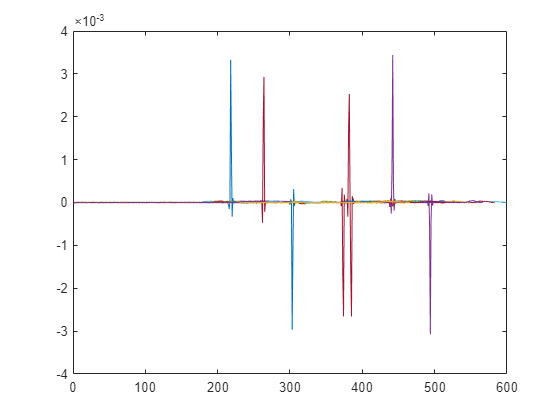

peakVeloscrubbed=rmoutliers(peakVelo);
m=round((1/3)*size(peakVeloscrubbed,1));
firstthirdsesh_peakvelo = peakVelo(1:m,:);
firstthirdsesh_peakvelo=rmoutliers(firsthalfsesh_peakvelo)
lastthirdsesh_peakvelo = peakVelo(2*m+1:end,:);

histogram(firstthirdsesh_mag,'EdgeColor','r','FaceColor','r', BinWidth=.00001)
hold on
histogram(lastthirdsesh_mag,'EdgeColor','b','FaceColor','b', BinWidth=.00001)
hold off 
legend('first third magnitude', 'last third magnitude')
title("saccade magnitude by session thirds (first and last)")
mean1st=mean(firsthalfsesh_mag)
mean2nd=mean(secondhalfsesh_mag)
std1st=std(firsthalfsesh_mag)

std2nd=std(secondhalfsesh_mag)

histogram(firstthirdsesh_peakvelo,'EdgeColor','r','FaceColor','r')
hold on
histogram(lastthirdsesh_peakvelo,'EdgeColor','b','FaceColor','b')
hold off 
legend('first third, peak velocity', 'last third, peak velocity')
title("peak saccade velocity by session halves")%%


%get eyex data into the form of display_target to start_target only; cells
%to contain the varying sizes. 
dataR22={};
for i= 1:size(dataRS,1)
    dataR22{i}=dataRS(i,12000:12000+(stampsS(i,3)*1000));
end

% plot data to verify that it looks okay 
for i= 1:size(dataRS,2); plot(dataRS{i}); hold on; end


%calculate the saccade velocity in the necessary time window
velo2={};
peakVelo2=[];
for i= 1:size(dataR22,2)
    velo2{i}=diff(abs(dataR22{i}));
    peaks2{i}=max(velo2{i});
    peakVelo2=cell2mat(peaks2);
end
peakVelo2=peakVelo2(:);
for i= 1:size(velo2,2); plot(velo2{i}); hold on; end



peakVelos2crubbed=rmoutliers(peakVelo2);
figure
histogram(peakVeloscrubbed,'EdgeColor','r','FaceColor','r',BinWidth=.000001)
hold on
histogram(peakVelos2crubbed,'EdgeColor','b','FaceColor','b',BinWidth=.000001)
hold off 
legend('Big', 'Small')
title("peak saccade velocity by reward size, session 109")%%%



diffy=zeros(101,499);
for i =1:101
    diffy(i,:)=diff(velos_SR(i,:));
end



plot(datameanqtr1,'-b')
hold on;
plot(datameanqtr1+datase1,'-k')
plot(datameanqtr1-datase1,'-k')
plot(datameanqtr4,'-g')
plot(datameanqtr4-datase4,'-k')
plot(datameanqtr4+datase4,'-k')
